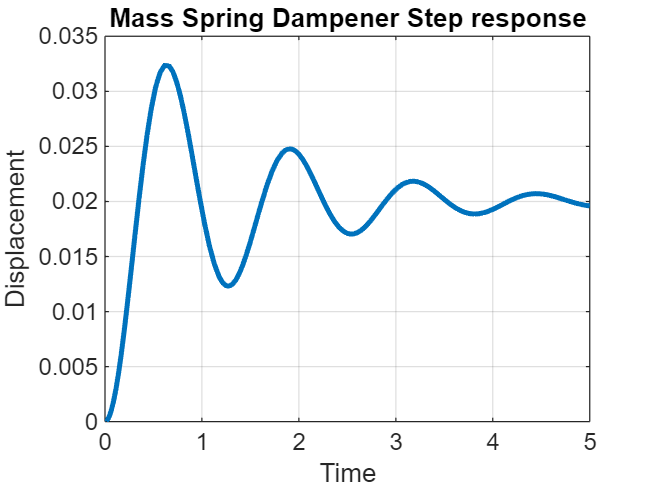

clear;clc;close all;
% system parameters

m = 2;
c = 3;
k = 50;
tspan = [0,5];
F = 1;

% intial conditions
x0 = [0,0];

 ode_func = @(t,x)[x(2);(F - c*x(2) - k*x(1))/m];
 [t, x_out] = ode45(ode_func,tspan, x0);

 figure
 plot(t,x_out(:,1),'LineWidth',2);
 title('Mass Spring Dampener Step response');
 ylabel('Displacement');
 xlabel('Time');
 grid on

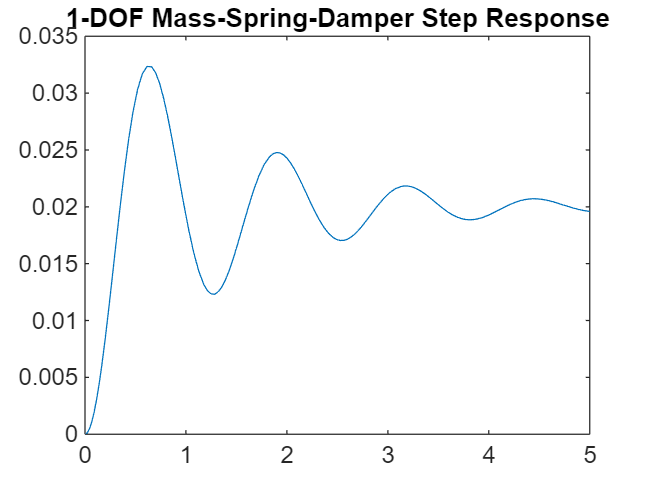

 plot(t ,x_out(:,1));
 title('1-DOF Mass-Spring-Damper Step Response');
saveas(gcf, 'step_response.png');